# Setup spatial maps

A 3*3 HC map

CurrentFolder = pwd

CurrentFolder = '/home/zx555/Documents/MATLAB/NYU-Vision-main/MFModel Code'

FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])

N_HC = 3; 
% Number of E and I neurons
n_E_HC = 54; n_I_HC = 31; % per side of HC
N_E = n_E_HC^2 * N_HC^2; % neuron numbers In all
N_I = n_I_HC^2 * N_HC^2;
% Grid sizes of E and I neurons; 
Size_HC = 0.500; % in mm;
Size_E = Size_HC/n_E_HC; Size_I = Size_HC/n_I_HC; 
% Projection: SD of distances
SD_E = 0.2/sqrt(2); SD_I = 0.125/sqrt(2);
Dist_LB = 0.36; % ignore the connection probability of dist>0.3mm
% Peak probability of projection
Peak_EE = 0.15; Peak_I = 0.6; 

% spatial indexes of E and I neurons
[NnE.X,NnE.Y] = V1Field_Generation(N_HC,1:N_E,'e');
[NnI.X,NnI.Y] = V1Field_Generation(N_HC,1:N_I,'i');

% determine connections between E, I
% sparse metrices containing 0 or 1. 
% Row_i Column_j means neuron j projects to neuron i
% add periodic boundary
C_EE = ConnectionMat(N_E,NnE,Size_E,...
                     N_E,NnE,Size_E,...
                     Peak_EE,SD_E,Dist_LB,1);

Elapsed time is 12.783223 seconds.



C_EI = ConnectionMat(N_E,NnE,Size_E,...
                     N_I,NnI,Size_I,...
                     Peak_I,SD_I,Dist_LB,0);

Elapsed time is 4.901443 seconds.



C_IE = ConnectionMat(N_I,NnI,Size_I,...
                     N_E,NnE,Size_E,...
                     Peak_I,SD_E,Dist_LB,0);

Elapsed time is 4.431365 seconds.



C_II = ConnectionMat(N_I,NnI,Size_I,...
                     N_I,NnI,Size_I,...
                     Peak_I,SD_I,Dist_LB,1);

Elapsed time is 1.585885 seconds.


## variables and parameters

initialize variables

% RefTimeE = zeros(N_E,1);
% VE = 0.5*rand(N_E,1)-0.5; SpE = sparse(N_E,1); 
% GE_ampa_R = zeros(N_E,1); GE_nmda_R = zeros(N_E,1); GE_gaba_R = zeros(N_E,1);
% GE_ampa_D = zeros(N_E,1); GE_nmda_D = zeros(N_E,1); GE_gaba_D = zeros(N_E,1);
% 
% RefTimeI = zeros(N_I,1);
% VI = 1.5*rand(N_I,1)-0.5; SpI = sparse(N_I,1);
% GI_ampa_R = zeros(N_I,1); GI_nmda_R = zeros(N_I,1); GI_gaba_R = zeros(N_I,1); 
% GI_ampa_D = zeros(N_I,1); GI_nmda_D = zeros(N_I,1); GI_gaba_D = zeros(N_I,1); 
load('Initials.mat')
%parameters
S_EE = 0.033; S_EI = 0.061; S_IE = 0.0087; S_II = 0.048;
%S_EE = 0.033; S_EI = 0.061; S_IE = 0.0087; S_II = 0.048;
%S_EE = 0.029; S_EI = 0.055; S_IE = 0.0081; S_II = 0.048; %Tuned
%S_EE = 0.028; S_EI = 0.056; S_IE = 0.0095; S_II = 0.042; % original
p_EEFail = 0.2; S_amb = 0.01;

tau_ampa_R = 0.5; tau_ampa_D = 3;
tau_nmda_R = 2; tau_nmda_D = 80;
tau_gaba_R = 0.5; tau_gaba_D = 5;
tau_ref = 2; % time unit is ms
dt = 0.2;
gL_E = 1/20;  Ve = 14/3; S_Elgn = 0.059; rhoE_ampa = 0.8; rhoE_nmda = 0.2;
gL_I = 1/15;  Vi = -2/3; S_Ilgn = 0.084; rhoI_ampa = 0.67;rhoI_nmda = 0.33;

lambda_E = 0.08; % ~16 LGN spike can excite a E neurons. 0.25 spike/ms makes 64 ms for such period. 
lambda_I = 0.08; 
rE_amb = 0.72; rI_amb = 0.36;
T = 5000; sampleT = 2; SimulationT = 500;

tic
[f_EnI,meanVs,loop] = MeanFieldEst_BkGd_Indep(C_EE,C_EI,C_IE,C_II,...
                                   S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                   lambda_E,S_Elgn,rE_amb,S_amb,...
                                   lambda_I,S_Ilgn,rI_amb,...
                                   tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,...
                                   rhoE_ampa,rhoE_nmda,rhoI_ampa,rhoI_nmda,...
                                   gL_E,gL_I,Ve,Vi,...
                                   N_HC,n_E_HC,n_I_HC);
toc

历时 0.201600 秒。


disp({['f_E = ' num2str(f_EnI(1,end))],['f_I = ' num2str(f_EnI(2,end))]})

    {'f_E = 4.3169'}    {'f_I = 14.7131'}



disp({['V_E = ' num2str(meanVs(1,end))],['V_I = ' num2str(meanVs(2,end))]})

    {'V_E = 0.51455'}    {'V_I = 0.69131'}



disp(['loop = ' num2str(loop)])

loop = 12


## updating dynamics

S_EE = 0.033, S_EI = 0.061, S_IE = 0.0087, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

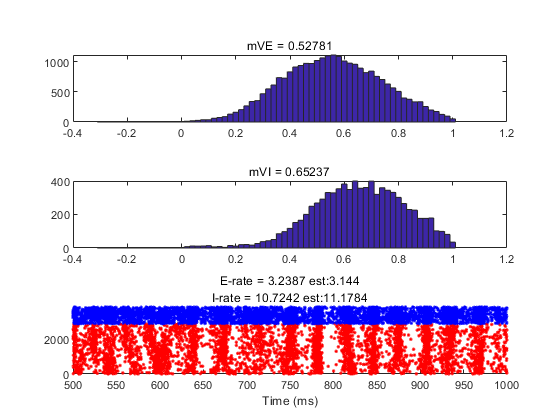


%E_SpHis= []; I_SpHis=[];
E_Sp = []; I_Sp = [];
VE_T = []; VI_T = [];
sampleN = floor(sampleT/dt); % sample each 2 ms
SimulationN = floor(SimulationT/dt); % show and check every 200ms
for TimeN = 1:floor(T/dt)
[oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,...
          oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
 oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
          oGI_ampa_D,oGI_nmda_D,oGI_gaba_D] = ...
          V1NetworkUpdate(RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,...
                                          GE_ampa_D,GE_nmda_D,GE_gaba_D,...
                          RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
                                          GI_ampa_D,GI_nmda_D,GI_gaba_D,...
                          C_EE,C_EI,C_IE,C_II,...
                          S_EE,S_EI,S_IE,S_II,...
                          tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
                          dt,p_EEFail,...
                          gL_E,Ve,S_Elgn,rhoE_ampa,rhoE_nmda,...
                          gL_I,Vi,S_Ilgn,rhoI_ampa,rhoI_nmda,...
                          S_amb,lambda_E,lambda_I,rE_amb,rI_amb);
                      
RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
                                          GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
                                          GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;

% When reaching every 200ms, demostrate and pause
if mod(TimeN,SimulationN) == 0 && TimeN*dt>500
    ParameterDisp = ['S_EE = ' num2str(S_EE) ', S_EI = ' num2str(S_EI) ...
          ', S_IE = ' num2str(S_IE) ', S_II = ' num2str(S_II) '\n' ...
          'S_Elgn = ' num2str(S_Elgn) ', lambda_E = ' num2str(lambda_E) ...
          ', S_Ilgn = ' num2str(S_Ilgn) ', lambda_I = ' num2str(lambda_I) '\n' ...
          'S_amb = ' num2str(S_amb) ', rE_amb = ' num2str(rE_amb) ', rI_amb = ' num2str(rI_amb)];

    
    fprintf(ParameterDisp)
    h = figure(1);
    subplot 311
    hist(oVE,-0.3:0.02:1)
    title(['mVE = ' num2str(nanmean(VE_T))])
    %E_SpHis = [E_SpHis,sum(oSpE)];
    %axis([-0.4 1.1 0 6000])
    
    subplot 312
    hist(oVI,-0.3:0.02:1)
    title(['mVI = ' num2str(nanmean(VI_T))])
    %I_SpHis = [I_SpHis,sum(oSpI)];
    %axis([-0.4 1.1 0 2000])
    
    E_sideInd = floor(1*n_E_HC+1):2*n_E_HC;
[E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);

I_sideInd = floor(1*n_I_HC+1):2*n_I_HC;
[I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);

%E_Ind = 10000:13000; I_Ind = 3300:4300;
scatterE = find(ismember(E_Sp(:,1),E_Ind));
scatterI = find(ismember(I_Sp(:,1),I_Ind));
[~,E_Fire_Ind] = ismember(E_Sp(scatterE,1),E_Ind);
[~,I_Fire_Ind] = ismember(I_Sp(scatterI,1),I_Ind);

WinSize = SimulationT;
T_RateWindow = [TimeN*dt-WinSize TimeN*dt];
E_SpInd = find(E_Sp(:,2)>=T_RateWindow(1) & E_Sp(:,2)<=T_RateWindow(2) & ismember(E_Sp(:,1),E_Ind));
I_SpInd = find(I_Sp(:,2)>=T_RateWindow(1) & I_Sp(:,2)<=T_RateWindow(2) & ismember(I_Sp(:,1),I_Ind));
E_Rate = length(E_SpInd)/(WinSize/1000)/length(E_Ind);
I_Rate = length(I_SpInd)/(WinSize/1000)/length(I_Ind);

f_EnIOneStep = MeanFieldEst_BkGd(N_EE,N_EI,N_IE,N_II,...
                                 S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                 lambda_E,S_Elgn,rE_amb,S_amb,...
                                 lambda_I,S_Ilgn,rI_amb,...
                                 gL_E,gL_I,Ve,Vi,nanmean(VE_T),nanmean(VI_T));

subplot 313
hold on
scatter(E_Sp(scatterE,2),E_Fire_Ind,'r.')
scatter(I_Sp(scatterI,2),I_Fire_Ind+max(E_Fire_Ind),'b.');
title({['E-rate = ' num2str(E_Rate) ' est:' num2str(f_EnIOneStep(1))],['I-rate = ' num2str(I_Rate) ' est:' num2str(f_EnIOneStep(2))]})
xlabel('Time (ms)')
xlim(T_RateWindow)
ylim([0 max(I_Fire_Ind)+max(E_Fire_Ind)])
drawnow
pause
close(h)
end

E_Sp = [E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]];
I_Sp = [I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]];
VE_T = [VE_T;nanmean(oVE(E_Ind))];
VI_T = [VI_T;nanmean(oVI(I_Ind))];
if sum(isnan(oVE))>0.6*N_E
    error('warning!: Network exploded')
end
end

% plots

% consider neurons in the center column
E_sideInd = floor(4/3*n_E_HC+1):5/3*n_E_HC;
[E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);

I_sideInd = floor(4/3*n_I_HC+1):5/3*n_I_HC;
[I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);

%E_Ind = 10000:13000; I_Ind = 3300:4300;
scatterE = find(ismember(E_Sp(:,1),E_Ind));
scatterI = find(ismember(I_Sp(:,1),I_Ind));
[~,E_Fire_Ind] = ismember(E_Sp(scatterE,1),E_Ind);
[~,I_Fire_Ind] = ismember(I_Sp(scatterI,1),I_Ind);

WinSize = 500;
T_RateWindow = [T-WinSize T];
E_SpInd = find(E_Sp(:,2)>=T_RateWindow(1) & E_Sp(:,2)<=T_RateWindow(2) & ismember(E_Sp(:,1),E_Ind));
I_SpInd = find(I_Sp(:,2)>=T_RateWindow(1) & I_Sp(:,2)<=T_RateWindow(2) & ismember(I_Sp(:,1),I_Ind));
E_Rate = length(E_SpInd)/(WinSize/1000)/length(E_Ind);
I_Rate = length(I_SpInd)/(WinSize/1000)/length(I_Ind);

close
figure(3)
hold on
scatter(E_Sp(scatterE,2),E_Fire_Ind,'r.')
scatter(I_Sp(scatterI,2),I_Fire_Ind+max(E_Fire_Ind),'b.');
title({['E-rate = ' num2str(E_Rate) ' est:' num2str(f_EnI(1))],['I-rate = ' num2str(I_Rate) ' est:' num2str(f_EnI(2))]})
xlabel('Time (ms)')
xlim([T-500 T])
ylim([0 max(I_Fire_Ind)+max(E_Fire_Ind)])
drawnow

## firing rate distribution

figure(4)
FiringEvents_NnE = zeros(size(VE));
FiringEvents_NnI = zeros(size(VI));
for NnInd = 1:N_E
    FiringEvents_NnE(NnInd) = length(find(E_Sp(:,1) == NnInd));
end
for NnInd = 1:N_I
    FiringEvents_NnI(NnInd) = length(find(I_Sp(:,1) == NnInd));
end
subplot 211
histogram(FiringEvents_NnE)
title('E Neuron Spike Dist');xlabel('Firing Rates (Hz)'); ylabel('Number of Neurons')
subplot 212
histogram(FiringEvents_NnI)
title('I Neuron Spike Dist');xlabel('Firing Rates (Hz)'); ylabel('Number of Neurons')

% Visualize firing rates
figure(5)
FiringE_Visualize = reshape(FiringEvents_NnE,N_HC*n_E_HC,N_HC*n_E_HC);
FiringI_Visualize = reshape(FiringEvents_NnI,N_HC*n_I_HC,N_HC*n_I_HC);
subplot 221
imagesc(FiringE_Visualize);colorbar;axis square
subplot 222
imagesc(FiringI_Visualize);colorbar;axis square

E_Block_ind = floor(n_E_HC/6);
E_Block = zeros(E_Block_ind);
for iiE = 1:E_Block_ind
    for jjE = 1:E_Block_ind
        Average_Field = FiringE_Visualize((iiE-1)*6+1:iiE*6, (jjE-1)*6+1:jjE*6);
        E_Block(iiE,jjE) = mean(mean(Average_Field));
    end
end

I_Block_ind = floor(n_I_HC/6);
I_Block = zeros(I_Block_ind);
for iiI = 1:I_Block_ind
    for jjI = 1:I_Block_ind
        Average_Field = FiringI_Visualize((iiI-1)*6+1:iiI*6, (jjI-1)*6+1:jjI*6);
        I_Block(iiI,jjI) = mean(mean(Average_Field));
    end
end

subplot 223
imagesc(E_Block);colorbar;axis square
subplot 224
imagesc(I_Block);colorbar;axis square

%save('Initials.mat','VE','SpE','GE_ampa_R','GE_nmda_R','GE_gaba_R',...
%                                'GE_ampa_D','GE_nmda_D','GE_gaba_D',...
%                     'VI','SpI','GI_ampa_R','GI_nmda_R','GI_gaba_R',...
%                                'GI_ampa_D','GI_nmda_D','GI_gaba_D')